# WorkSheet 9

Problem 1

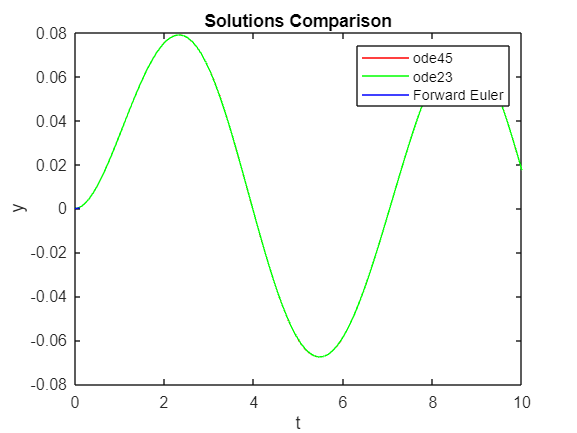

% Part 1
% Define the differential equation
f = @(t, y) -y + sin(y^2) + 0.1*sin(t);
% Initial condition
y0 = 0;
% Time span
tspan = linspace(0,10);
% Solve the differential equation using ode45
[t, y] = ode45(f, tspan, y0);

% Part 2 
% Set options for ode23
options = odeset('RelTol',1e-10,'AbsTol',1e-10);
% Solve the differential equation using ode23
[t2, y2] = ode23(f, tspan, y0, options);

% Part 3
% Step size
h = 0.01;
% Calculate the number of steps
nsteps = ceil((tspan(2) - tspan(1)) / h);
% Initialize arrays for time and solution
t_euler = tspan(1):h:tspan(2);
y_euler = zeros(1, nsteps);
% Initial condition
y_euler(1) = y0;
% Forward Euler method
for i = 1:(nsteps-1)
    y_euler(i+1) = y_euler(i) + h * f(t_euler(i), y_euler(i));
end

% Part 4
figure;
plot(t, y, 'r', t2, y2, 'g', t_euler, y_euler, 'b');
title('Solutions Comparison');
xlabel('t');
ylabel('y');
legend('ode45', 'ode23', 'Forward Euler');


% Part 5
% "Stiff ODEs" are differential equations for which certain numerical methods (like explicit methods) are unstable unless the step size is taken to be extremely small. 
%  In MATLAB, ode45 and ode23 are designed to handle stiff ODEs, but they do so in different ways. ode45 uses a stiffly stable implicit Runge-Kutta method, while ode23 uses a backward differentiation formula. The choice between these solvers depends on the specific characteristics of the ODE being solved.

Problem 2

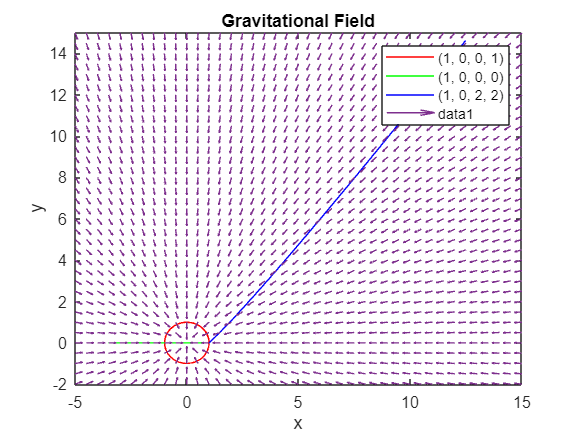

% Part 1
% Define the system of equations
f = @(t, y) [y(3); y(4); -y(1)./(y(1).^2 + y(2).^2); -y(2)./(y(1).^2 + y(2).^2)];
% Initial conditions
ic_1 = [1; 0; 0; 1];
% Time span
tspan = linspace(0,10);
% Solve the system using ode45
[t, Y] = ode45(f, tspan, ic_1);
% Plot the orbits

% Part 2
% Initial conditions
ic_2 = [1; 0; 0; 0];
% Solve the system using ode45
[t_2, Y_2] = ode45(f, tspan, ic_2);

% Part 3
% Initial conditions
ic_3 = [1; 0; 2; 2];
% Solve the system using ode45
[t_3, Y_3] = ode45(f, tspan, ic_3);


% Part 4
% Plot all orbits on the same plot
figure;
plot(Y(:,1), Y(:,2), 'r', Y_2(:,1), Y_2(:,2), 'g', Y_3(:,1), Y_3(:,2), 'b');
legend('(1, 0, 0, 1)', '(1, 0, 0, 0)', '(1, 0, 2, 2)');

% Part 5
hold on
% Define the gravitational field
x0 = -5;
x1 = 15;
y0 = -2;
y1 = 15;
h = 0.5; 
scale = 0.5;
dx = @(x,y) -x./(x.^2+y.^2);
dy = @(x,y) -y./(x.^2+y.^2);
% Plot the gravitational field
[U1,V1] = myQuiver(x0,x1,y0,y1,h,dy,dx,scale);
title('Gravitational Field');
hold off
xlabel('x');
ylabel('y');

Problem 3

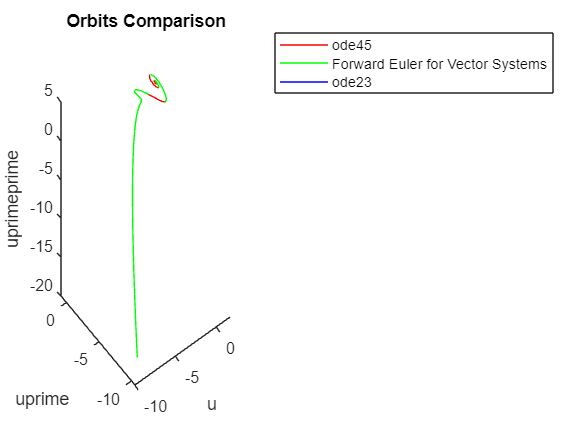

% Part 1
f = @(t,y) [y(2);y(3);0.4-(0.2.*y(3))-y(2)-0.5.*y(1).^2];
ic = [sqrt(0.8); 0; 0];
tspan = linspace(0,100,1000);
% Solve with ode23
[t23, y23] = ode23(f, tspan, ic);

% Part 2
% Solve with ode45
[t45, y45] = ode45(f, tspan, ic);

% Part 3
[t,v] = forward_euler_vec(f,tspan, ic, 1000);

% Part 4
figure;
plot3(y23(:,1), y23(:,2), y23(:,3), 'r', y45(:,1), y45(:,2), y45(:,3),'g',v(:,1), v(:,2), v(:,3), 'b');
title('Orbits Comparison');
xlabel('u');
ylabel('uprime');
zlabel('uprimeprime');
legend('ode45', 'Forward Euler for Vector Systems', 'ode23');


% Part 5
% Stiff ODEs can cause explicit methods like Forward Euler to require very small step sizes for stability, whereas ode23 and ode45 might handle the stiffness more gracefully due to their adaptive step-size algorithms. Stiffness is an important aspect to consider in choosing an appropriate solver for a given ODE problem.
% In summary, extending the time span to [0, 100] allows you to observe the long-term behavior of the system, which can provide insights into the system's stability, the presence of stiffness, and the impact of non-linear dynamics. This can be particularly useful for understanding the behavior of complex systems and for selecting appropriate numerical methods for solving such systems.